load('WT_File');
data_xes = xes; % same for all files
data_patchxes = patchxes; % same for all files
WT_mean = dataMean;
WT_ci = dataPatch;

load('mutant_File')
mutant_mean = dataMean;
mutant_ci = dataPatch;




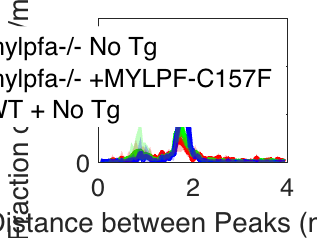

ax =   Axes with properties:

             XLim: [0 4]
             YLim: [0 0.1500]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% plot results
figure()
plot(data_xes, mutant_mean, 'r', 'linewidth',3)
hold on
plot(data_xes, WT_mean, 'b', 'linewidth',3)

patch(data_patchxes, mutant_ci, 'r', "FaceAlpha", 0.25, 'LineStyle', 'none')
patch(data_patchxes, WT_ci,'b', "FaceAlpha", 0.25, 'LineStyle', 'none')

xlabel('Distance between Peaks (micron)', 'FontSize', 28)
ylabel('Fraction of peaks/micron', 'FontSize',28)
xlim([0, 4])
ylim([0,0.15])
%title('Title', 'FontSize', 16)

legend('mutant', 'WT', "FontSize", 14, "Location", 'NorthEast')
legend('boxoff')
ax = gca;
ax.FontSize = 14